# **01 - Initial Sizing and Baseline**

# A - Initial Sizing

**Takeoff Gross Weight = Fixed Mass + Varying Mass**


$$W_0 =W_{\textrm{crew}} +W_{\textrm{payload}} +W_{\textrm{fuel}} +W_{\textrm{empty}}$$



$$\;\;\;\;\;\;=W_{\textrm{crew}} +W_{\textrm{payload}} +\frac{W_f }{W_0 }W_0 +\frac{W_e }{W_0 }W_e$$


$\;\;\;\;\;\;=\frac{W_{\textrm{crew}} +W_{\textrm{payload}} }{1-\frac{W_f }{W_0 }-\frac{W_e }{W_0 }}$d

$\frac{{\mathit{\mathbf{W}}}_{\mathit{\mathbf{e}}} }{{\mathit{\mathbf{W}}}_0 }$** estimated from historical data** (Raymer p.31)


$$\frac{W_e }{W_0 }={{\textrm{AW}}_0 }^C$$


$\frac{{\mathit{\mathbf{W}}}_{\mathit{\mathbf{f}}} }{{\mathit{\mathbf{W}}}_0 }$** estimated from mission profile**

**0-1 **Taxi & Takeoff

**1-2** Climb and accelerate to cruise

**2-3 **Cruise for an air distance of 7500 nmi at Mach 0.83

**3-4** Descent to land

**4-5** Missed approach, followed by clmb and accelerate to alternate

**5-6** Cruise to alternate destination 370 km away

**6-7** Loiter at 5000 ft for 45 minutes

**7-8** Descent to land

**8-9** Landing & Taxi

**for cruise  **$\frac{W_i }{W_{i-1} }=e^{-\frac{\textrm{RC}}{V\left(\frac{L}{D}\right)}}$  (Breguet equation)  **at **${0\ldotp 866\left(\frac{\mathit{\mathbf{L}}}{\mathit{\mathbf{D}}}\right)}_{\max }$(Raymer p.41)

**for loiter   ** $\frac{W_i }{W_{i-1} }=e^{-\frac{\textrm{EC}}{\frac{L}{D}}}$       (Breguet equation)  **at **${\left(\frac{\mathit{\mathbf{L}}}{\mathit{\mathbf{D}}}\right)}_{\max }$ (Raymer p.41)

**where  **${\left(\frac{L}{D}\right)}_{\max } =K_{\textrm{LD}} \sqrt{\frac{\textrm{AR}}{\frac{S_{\textrm{wet}} }{S_{\textrm{ref}} }}}\;$ **and ** $A_{\textrm{wetted}} =\frac{b^2 }{S_{\textrm{wetted}} }=\frac{A}{\left(\frac{S_{\textrm{wet}} }{S_{\textrm{ref}} }\right)}$

% House Keeping
clear
clc
close all

**Basic Parameters**

% Weight
W_crew = 500 * 82.8;                     % Passenger weight + carry-on luggage (kg) % Ref 04 p.45
W_crew = W_crew + (12 + 4) * 79.4;       % Crew weight + carry-on luggage (kg)      % Roskam Part I p.8
W_payload = 500 * 17;                    % Passener checked luggage (kg)            % Ref 04 p.45
W_payload = W_payload + (12 + 4) * 13.6; % Crew checked luggage (kg)                % Roskam Part I p.8

% W_0 = 0;                               % Takeoff gross weight (kg)
% W_f_0 = 0;                             % W_fuel / W_0
% W_e_0 = 0;                             % W_empty weight / W_0

g = 9.80665;                             % Standard acceleration of gravity (m/s^2)

**Empirical **$\frac{{\mathit{\mathbf{W}}}_{\mathit{\mathbf{f}}} }{{\mathit{\mathbf{W}}}_0 }$** Data**

% Warmup and Takeoff
W_TO_Ry = 0.970;                 % W_i / W_i-1 % Raymer p.34
W_TO_Rk = 0.99 .* 0.99 .* 0.995; % W_i / W_i-1 % Roskam Part I p.12

% Climb and Accelerate to cruise
W_C_Ry = 0.985;                  % W_i / W_i-1 % Raymer p.34
W_C_Rk = 0.980;                  % W_i / W_i-1 % Roskam Part I p.12

% Descent to land
W_D_Ry = 0.990; % 0.990 to 0.995 % W_i / W_i-1 % Raymer p.153
W_D_Rk = 0.990;                  % W_i / W_i-1 % Roskam Part I p.12

% Landing and Taxi
W_L_Ry = 0.992; % 0.992 to 0.997 % W_i / W_i-1 % Raymer p.34 (p.153)
W_L_Rk = 0.992;                  % W_i / W_i-1 % Roskam Part I p.12

**Empirical Airplane Data**

AR = 8;            % Aspect ratio        % Respectively, a lower Aspect Ratio has been chosen since the Reference Code 4E and also reduce structural challenge
WR = 4.5;          % S_wet / S_ref       % Raymer p.40 we read from the graph
AR_W = AR ./ WR;   % Wetted aspect ratio
K_LD = 15.5;       % For civil jets      % Raymer p.40

LD_max = K_LD .* (AR_W) .^ 0.5;     % L/D_max       % Raymer p.41
LD_cruise = 0.866 .* LD_max;        % L/D_cruise    % Raymer p.41
LD_alternate = (10 / 18) .* LD_max; % L/D_alternate % Roskam p.57

**Empirical Engine Data**

NE = 4; % Number of engines

High-bypass Turbofan

% C_cruise = 0.5 ./ 3600; % SFC (1/s) % Raymer p.36
% C_loiter = 0.4 ./ 3600; % SFC (1/s) % Raymer p.36

GE9X

% W_engine = 9630; % Weight of engine (kg)
% T_0 = 489300;    % Takeoff thrust (N)
% T_0 = T_0 * 1.05;% Rubber engine
% T_c = TBD;       % Maximum continuous thrust (N)
% BPR = 10;          % Bypass Ratio % GE9X % Wikipedia

% C_cruise = (0.478 .* 0.95) ./ 3600; % SFC (1/s) % 5% lower SFC than the XWB-97 % Wikipedia
% C_loiter = 0.8 .* C_cruise;         % SFC (1/s) % 80% cruise SFC  % Raymer p.36
% C_alternate = 1.15 .* C_cruise;     % SFC (1/s) % 115% cruise SFC % Ref12

Trent 972E-84 

% W_engine = 9630; % Weight of engine (kg)
T_0 = 320300;      % Takeoff thrust (N)
T_0 = T_0 * 1.05;  % Rubber engine
% T_c = TBD;       % Maximum continuous thrust (N)
BPR = 8.5;         % Bypass Ratio % Trent 972E-84 % Ref 17

C_cruise = 0.5 ./ 3600;         % SFC (1/s) % Raymer p.36
C_loiter = 0.4 ./ 3600;         % SFC (1/s) % Raymer p.36
C_alternate = 1.15 .* C_cruise; % SFC (1/s) % 115% cruise SFC % Ref12
% C_alternate =  C_cruise; % SFC (1/s) % 115% cruise SFC % Ref12

% Housekeeping
clearvars WR AR_W K_LD

**Calculate Fuel Fraction **

**0-1** Taxi & Takeoff

W_10_Ry = W_TO_Ry;
W_10_Rk = W_TO_Rk;

**1-2** Climb and accelerate to cruise

W_21_Ry = W_C_Ry;
W_21_Rk = W_C_Rk;

**2-3** Cruise for an air distance of 7500 nmi at Mach 0.83

% Cruise altitude 39,000 ft align with Boeing 777 % Wikipedia

R_32 = convlength(7500, 'naut mi','m'); % Range (m)
h_32 = convlength(39000, 'ft','m');     % Cruise altitude (m)

[T_32, c_32, P_32, rho_32] = atmosisa(h_32);

V_32 = 0.83 * c_32;                     % Velocity (m/s)
LD_32 = LD_cruise;                      % Optimal cruise L/D ratio

% Breguet range equation
W_32 = exp((-R_32 .* C_cruise) ./ (V_32 .* LD_32));

**3-4** Descent to land

W_43_Ry = W_D_Ry;
W_43_Rk = W_D_Rk;

**4-5** Missed approach, followed by clmb and accelerate to alternate

W_54_Ry = W_C_Ry;
W_54_Rk = W_C_Rk;

**5-6** Cruise to alternate destination 370 km away

% Cruise altitude 18,000 ft for Lost Communications Missed Approach % Ref 5
% Assume cruise velocity 400 knots                                  % Ref 5

R_65 = convlength(370, 'km', 'm');  % Range (m)
h_65 = convlength(18000, 'ft','m'); % Alternate altitude (m)

% [T_65, c_65, P_65, rho_65] = atmosisa(h_65);

V_65 = convvel(400, 'kts', 'm/s');  % Alternate velocity (m/s)
LD_65 = LD_alternate;               % Estimate alternate L/D ratio

% Breguet range equation
W_65 = exp((-R_65 .* C_alternate) ./ (V_65 .* LD_65));

**6-7** Loiter at 5000 ft for 45 minutes

E_76 = 45 * 60; % Endurance (s)
LD_76 = LD_max; % Optimal loiter L/D ratio

% Breguet endurance equation
W_76 = exp((-E_76 .* C_loiter) ./ LD_76);

**7-8** Descent to land

W_87_Ry = W_D_Ry;
W_87_Rk = W_D_Rk;

**8-9** Landing & Taxi

W_98_Ry = W_L_Ry;
W_98_Rk = W_L_Rk;

Plot table for fuel fraction 

col1 = ["0-1", "1-2", "2-3", "3-4", "4-5", "5-6", "6-7", "7-8", "8-9"];
col2 = [W_10_Ry, W_21_Ry, W_32, W_43_Ry, W_54_Ry, W_65, W_76, W_87_Ry, W_98_Ry];
col3 = cumprod(col2);
col4 = [W_10_Rk, W_21_Rk, W_32, W_43_Rk, W_54_Rk, W_65, W_76, W_87_Rk, W_98_Rk];
col5 = cumprod(col4);
T = table(col1', col2', col3', col4', col5', 'VariableNames', ...
    {'Leg', 'Wi/Wi-1 (Raymer)', 'Culmulative (Raymer)', 'Wi/Wi-1 (Roskam)', 'Culmulative (Roskam)'});
disp(T)

     Leg     Wi/Wi-1 (Raymer)    Culmulative (Raymer)    Wi/Wi-1 (Roskam)    Culmulative (Roskam)
    _____    ________________    ____________________    ________________    ____________________

    "0-1"           0.97                  0.97                0.9752                0.9752       
    "1-2"          0.985               0.95545                  0.98                0.9557       
    "2-3"        0.64395               0.61527               0.64395               0.61542       
    "3-4"           0.99               0.60911                  0.99               0.60927       
    "4-5"          0.985               0.59998                  0.98               0.59708       
    "5-6"         0.9753               0.58516                0.9753               0.58233       
    "6-7"        0.98559               0.5767

Culmulative fuel fraction


$$\frac{W_f }{W_0 }=1\ldotp 01\left(1-\frac{W_x }{W_0 }\right)$$


W_f_0_Ry = 1.01 .* (1 - W_10_Ry .* W_21_Ry .* W_32 .* W_43_Ry .* W_54_Ry .* W_65 .* W_76 .* W_87_Ry .* W_98_Ry)

W_f_0_Ry = 0.4379

W_f_0_Rk = 1.01 .* (1 - W_10_Rk .* W_21_Rk .* W_32 .* W_43_Rk .* W_54_Rk .* W_65 .* W_76 .* W_87_Rk .* W_98_Rk)

W_f_0_Rk = 0.4407

% Store Value into Matrix
W_i = [W_10_Ry W_21_Ry W_32 W_43_Ry W_54_Ry W_65 W_76 W_87_Ry W_98_Ry]; % Raymer
% W_i = [W_10_Rk W_21_Rk W_32 W_43_Rk W_54_Rk W_65 W_76 W_87_Rk W_98_Rk]; % Roskam

% Housekeeping
clearvars R_32 V_32 LD_32 h_32 T_32 c_32 P_32 rho_32
clearvars R_65 V_65 LD_65 h_65 % T_65 c_32 P_65 rho_65
clearvars E_76 LD_76
clearvars W_10_Ry W_10_Rk W_21_Ry W_21_Rk W_32 W_43_Ry W_43_Rk W_54_Ry W_54_Rk
clearvars W_65 W_76 W_87_Ry W_87_Rk W_98_Ry W_98_Rk
clearvars col1 col2 col3 col4 col5 T
clearvars W_TO_Ry W_TO_Rk W_C_Ry W_C_Rk W_D_Ry W_D_Rk W_L_Ry W_L_Rk

**Calculate Empty Weight Fraction**

% Guess Takeoff gross weight (kg)
W_0 = zeros(2000, 1);

for i = 1:2000
    W_0(i) = 100000 + 750 * i;
end

% W_0 = linspace(100e3, 600e3, 1000) .* g; % Takeoff gross weight (kg)

From regression of historical data (Raymer p.31)


$$\frac{W_E }{W_0 }={\textrm{AW}}_o^C$$


A_Ry = 0.97;  % Constant from jet transport historical data % Raymer p.31
C_Ry = -0.06; % Constant from jet transport historical data % Raymer p.31
W_e_0_Ry = A_Ry .* W_0 .^ C_Ry;

From regression of historical data (Roskam p.18)


$$W_E ={10}^{\frac{\log_{10} \left(W_0 \right)-A}{B}}$$


A_Rk = 0.0833;  % Constant from jet transport historical data % Raymer p.31
B_Rk = 1.0383; % Constant from jet transport historical data % Raymer p.31
W_e_0_Rk = (10 .^ ((log10(W_0) - A_Rk) ./ B_Rk)) ./ W_0;

From regression of historical data (Wikipedia [Fuel fraction - Wikipedia](https://en.wikipedia.org/wiki/Fuel_fraction))

% Wikipedia: Fuel fraction
W_0_Data = [575 351.5 347.8 347.5 186.9 322 283 319 254.7 242 242 233 227.9]' .* 10 .^ 3;
W_e_0_Data = [0.496 0.477 0.415 0.418 0.461 0.481 0.503 0.413 0.506 0.535 0.498 0.47 0.527]';
W_f_0_Data = [0.442	0.414 0.418 0.419 0.393 0.387 0.39 0.413 0.399 0.451 0.451 0.469 0.444]';

% Define the fitting model as A * W0 ^ c
fitModel = fittype('A * x ^ c', 'independent', 'x', 'coefficients', {'A', 'c'});

% Perform the fitting
[fitResult, gofe] = fit(W_0_Data, W_e_0_Data, fitModel);

r_squared_e = gofe.rsquare

r_squared_e = 0.0722

W_e_0_Real = fitResult.A .* W_0 .^ fitResult.c;

% Define the fitting model as B * W0
mdl = fitlm(W_0_Data, W_f_0_Data);
r_squared_f = mdl.RMSE

r_squared_f = 0.0279

W_f_0_Real = 4.950539503574920e-09 .* W_0 + 0.4208;

Plot the data

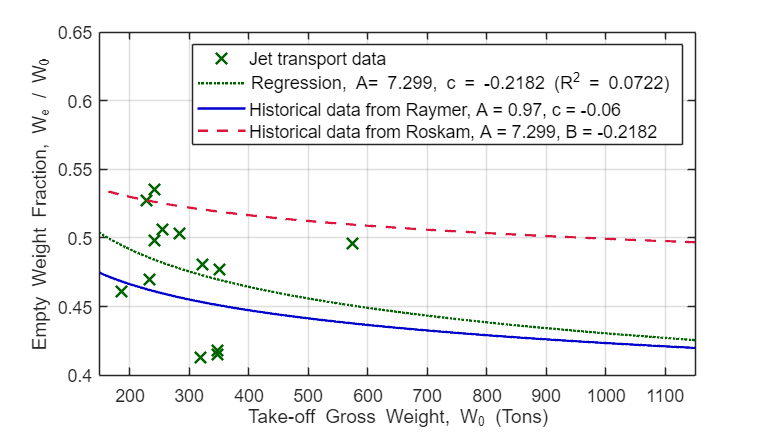

figure(1)

clf

plot(W_0_Data ./ 1000, W_e_0_Data, 'x', 'Color', [0/255 100/255 0/255], 'MarkerSize', 10, 'LineWidth', 1.5)
hold on
plot(W_0 ./ 1000, W_e_0_Real, ':', 'Color', [0/255 100/255 0/255], 'LineWidth', 1.5);
hold on
plot(W_0 ./ 1000, W_e_0_Ry, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5);
hold on
plot(W_0 ./ 1000, W_e_0_Rk, '--', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5);
hold off

legend('Jet transport data', ...
       "Regression, A= 7.299, c = -0.2182 (R^{2} = 0.0722)", ...
       "Historical data from Raymer, A = 0.97, c = -0.06", ...
       "Historical data from Roskam, A = 7.299, B = -0.2182", ...
       'Location', 'NorthEast', 'NumColumns', 1, FontSize = 11)

xlabel('Take-off Gross Weight, W_{0} (Tons)'); 
ylabel('Empty Weight Fraction, W_{e} / W_{0}');

set(gca, 'FontSize', 11) % set the fontsize of the axis

xlim([150 1150]);
ylim([0.4 0.65]);

grid on;                             % set the grid of the graph
set(gcf, 'Position', [0 0 640 360]); % show plot with larger size

**Estimate Takeoff Gross Weight**

We need solution satisfies both equations below

- $\frac{W_e }{W_0 }={{\textrm{AW}}_0 }^C$ (from regression of historical data)

- 
$$W_0 =\frac{W_{\textrm{crew}} +W_{\textrm{payload}} }{1-\frac{W_f }{W_0 }-\frac{W_e }{W_0 }}$$


Plot empty weight fraction from both equations and see where they cross for historical data

% From weight build-up calculations
W_e_0_Cal_Ry = 1 - W_f_0_Ry - (W_crew + W_payload) ./ W_0; % Raymer p.34
W_e_0_Cal_Rk = 1 - W_f_0_Rk - (W_crew + W_payload) ./ W_0; % Roskam Part I p.12

% Caculate exact value of solution

func_Ry = @(W0) ((W_crew + W_payload) / (1 - W_f_0_Ry - A_Ry * W0 ^ C_Ry)) - W0; % Define the function to solve for W0
    
W0_initial_guess = 4000000;  % Adjust based on expected range
    
W0_solution_Ry = fsolve(func_Ry, W0_initial_guess);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



W0_solution = W0_solution_Ry;

func_Rk = @(W0) ((W_crew + W_payload) / (1 - W_f_0_Rk - (10 .^ ((log10(W0) - A_Rk) ./ B_Rk)) ./ W0)) - W0; % Define the function to solve for W0
    
W0_solution_Rk = fsolve(func_Rk, W0_initial_guess);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


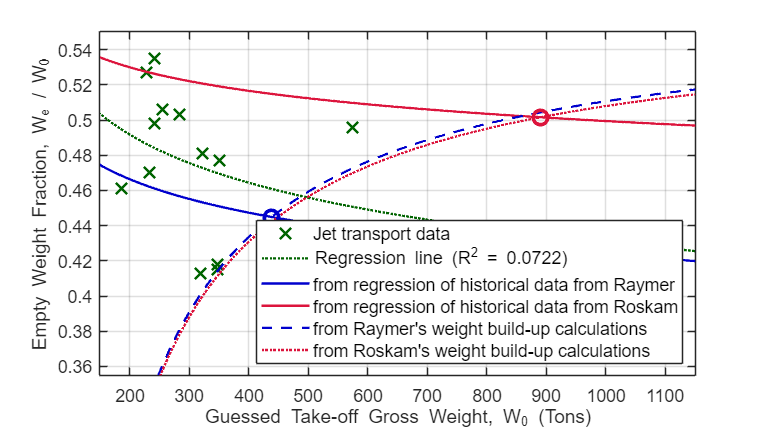


% Plot
figure(2)

clf

plot(W_0_Data ./ 1000, W_e_0_Data, 'x', 'Color', [0/255 100/255 0/255], 'MarkerSize', 10, 'LineWidth', 1.5)
hold on
plot(W_0 ./ 1000, W_e_0_Real, ':', 'Color', [0/255 100/255 0/255], 'LineWidth', 1.5);
hold on
plot(W_0 ./ 1000, W_e_0_Ry, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5);
hold on
plot(W_0 ./ 1000, W_e_0_Rk, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5);
hold on
plot(W_0 ./ 1000, W_e_0_Cal_Ry, '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5);
hold on
plot(W_0 ./ 1000, W_e_0_Cal_Rk, ':', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5);
hold on

plot(W0_solution_Ry ./ 1000, 0.97 * W0_solution_Ry ^ C_Ry, 'o', 'Color', [0/255 0/255 205/255], 'MarkerSize', 9, 'LineWidth', 2.25)
hold on

plot(W0_solution_Rk ./ 1000, (10 .^ ((log10(W0_solution_Rk) - A_Rk) ./ B_Rk)) ./ W0_solution_Rk, 'o', 'Color', [220/255 20/255 60/255], 'MarkerSize', 9, 'LineWidth', 2.25)
hold off

% x1 = xline(W0_solution_Rk ./ 1000, '-', {sprintf('%.2f (%.4f)', W0_solution_Rk ./ 1000, 0.97 * W0_solution_Rk ^ C_Ry)}, ...
    % 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5);

% x2 = xline(W0_solution_Ry ./ 1000, '-', {sprintf('%.2f (%.4f)', W0_solution_Ry ./ 1000, 0.97 * W0_solution_Ry ^ C_Ry)}, ...
    % 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5);
% x2.LabelHorizontalAlignment = 'left';

legend('Jet transport data', ...
       "Regression line (R^{2} = 0.0722)", ...
       'from regression of historical data from Raymer', ...
       'from regression of historical data from Roskam', ...
       "from Raymer's weight build-up calculations", ...
       "from Roskam's weight build-up calculations", ...
       'Location', 'SouthEast', 'NumColumns', 1, FontSize = 11)

xlabel('Guessed Take-off Gross Weight, W_{0} (Tons)'); 
ylabel('Empty Weight Fraction, W_{e} / W_{0}');

set(gca, 'FontSize', 11) % set the fontsize of the axis

xlim([150 1150]);
ylim([0.355 0.55]);

grid on;                             % set the grid of the graph
set(gcf, 'Position', [0 0 640 360]); % show plot with larger size 

Plot empty weight fraction from both equations and predicted $W_0$

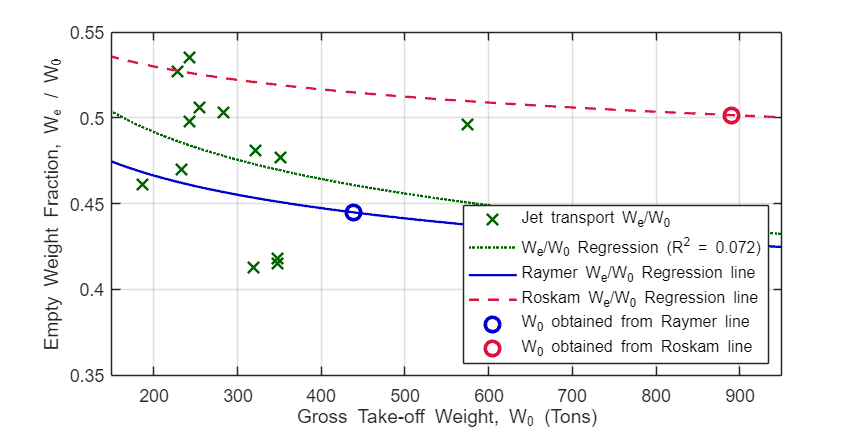

% Plot
figure(3)

clf

plot(W_0_Data ./ 1000, W_e_0_Data, 'x', 'Color', [0/255 100/255 0/255], 'MarkerSize', 10, 'LineWidth', 1.5)
hold on
plot(W_0 ./ 1000, W_e_0_Real, ':', 'Color', [0/255 100/255 0/255], 'LineWidth', 1.5);
hold on
plot(W_0 ./ 1000, W_e_0_Ry, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5);
hold on
plot(W_0 ./ 1000, W_e_0_Rk, '--', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5);
hold on

plot(W0_solution_Ry ./ 1000, 0.97 * W0_solution_Ry ^ C_Ry, 'o', 'Color', [0/255 0/255 205/255], 'MarkerSize', 9, 'LineWidth', 2.25)
hold on
plot(W0_solution_Rk ./ 1000, (10 .^ ((log10(W0_solution_Rk) - A_Rk) ./ B_Rk)) ./ W0_solution_Rk, 'o', 'Color', [220/255 20/255 60/255], 'MarkerSize', 9, 'LineWidth', 2.25)
hold off

legend('Jet transport W_{e}/W_{0}', ...
       "W_{e}/W_{0} Regression (R^{2} = 0.072)", ...
       'Raymer W_{e}/W_{0} Regression line', ...
       'Roskam W_{e}/W_{0} Regression line', ...
       'W_{0} obtained from Raymer line', ...
       'W_{0} obtained from Roskam line', ...
       'Location', 'SouthEast', 'NumColumns', 1, FontSize = 10)

xlabel('Gross Take-off Weight, W_{0} (Tons)'); 
ylabel('Empty Weight Fraction, W_{e} / W_{0}');

set(gca, 'FontSize', 11) % set the fontsize of the axis

xlim([150 950]);
ylim([0.35 0.55]);

grid on;                             % set the grid of the graph
set(gcf, 'Position', [0 0 720 360]); % show plot with larger size 

Plot fuel fraction from both equations and predicted $W_0$

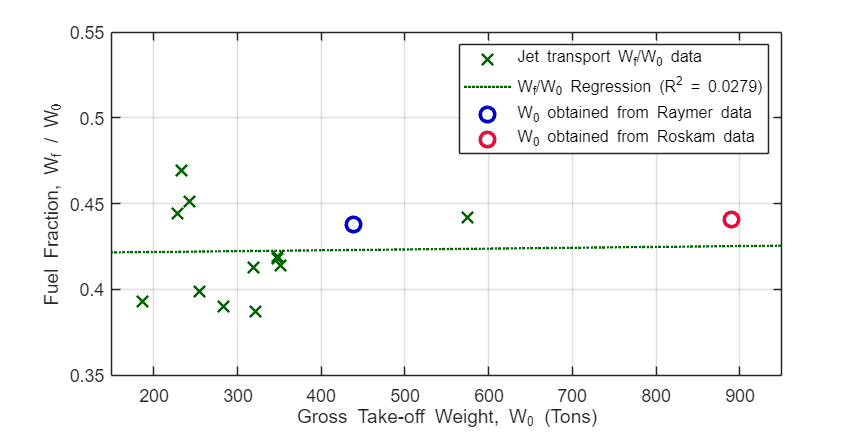

% Plot
figure(3)

clf

plot(W_0_Data ./ 1000, W_f_0_Data, 'x', 'Color', [0/255 100/255 0/255], 'MarkerSize', 10, 'LineWidth', 1.5)
hold on
plot(W_0 ./ 1000, W_f_0_Real, ':', 'Color', [0/255 100/255 0/255], 'LineWidth', 1.5);
hold on

plot(W0_solution_Ry ./ 1000, W_f_0_Ry, 'o', 'Color', [0/255 0/255 205/255], 'MarkerSize', 9, 'LineWidth', 2.25)
hold on
plot(W0_solution_Rk ./ 1000, W_f_0_Rk, 'o', 'Color', [220/255 20/255 60/255], 'MarkerSize', 9, 'LineWidth', 2.25)
hold off

legend('Jet transport W_{f}/W_{0} data', ...
       "W_{f}/W_{0} Regression (R^{2} = 0.0279)", ...
       'W_{0} obtained from Raymer data', ...
       'W_{0} obtained from Roskam data', ...
       'Location', 'NorthEast', 'NumColumns', 1, FontSize = 10)

xlabel('Gross Take-off Weight, W_{0} (Tons)'); 
ylabel('Fuel Fraction, W_{f} / W_{0}');

set(gca, 'FontSize', 11) % set the fontsize of the axis

xlim([150 950]);
ylim([0.35 0.55]);

grid on;                             % set the grid of the graph

set(gcf, 'Position', [0 0 720 360]); % show plot with larger size 

% Output result
W_0 = W0_solution  % Take-off gross weight (kg) % Raymer

W_0 = 4.3859e+05

% W_0 = 380 * 1e3; % Take-off gross weight (kg) % Regression
W_e_0 = 0.97 * W0_solution_Ry ^ C_Ry

W_e_0 = 0.4449

W_e = W_e_0 * W_0

W_e = 1.9512e+05

W_f = W_f_0_Ry * W_0

W_f = 1.9208e+05


% Housekeeping
clearvars x1 x2 x3 x4 W_e_0_Cal_Ry W_e_0_Cal_Rk W_0_Est_Ry W_0_Est_Rk W_0_Data
clearvars W_e_0_Ry W_e_0_Rk W_e_0_Real W_f_0_Real W_e_0_Data W_f_0_Data
clearvars fitModel fitResult gofe goff mdl
clearvars W0_solution_Ry W0_solution_Rk W0_initial_guess W0_solution

# B - Sizing to Constraint

**Reasons**

- Make sure aircraft can **complete mission profile**

- Make sure aircraft capable of **achieving performance targets **(stall speed, takeoff landing distance, climb rate, ceiling, turn rates)

- Make sure aircraft** meets airworthiness requirements**.

**Key Parameters**

- Thrust to weight ratio $\frac{\mathit{\mathbf{T}}}{\mathit{\mathbf{W}}}$ **at given altitude**

- Wing loading $\frac{\mathit{\mathbf{W}}}{\mathit{\mathbf{S}}}$

- Maximum lift coefficient ${\mathit{\mathbf{C}}}_{{\mathit{\mathbf{L}}}_{\max } }$ **at takeoff, landing and cruising**

**Example**

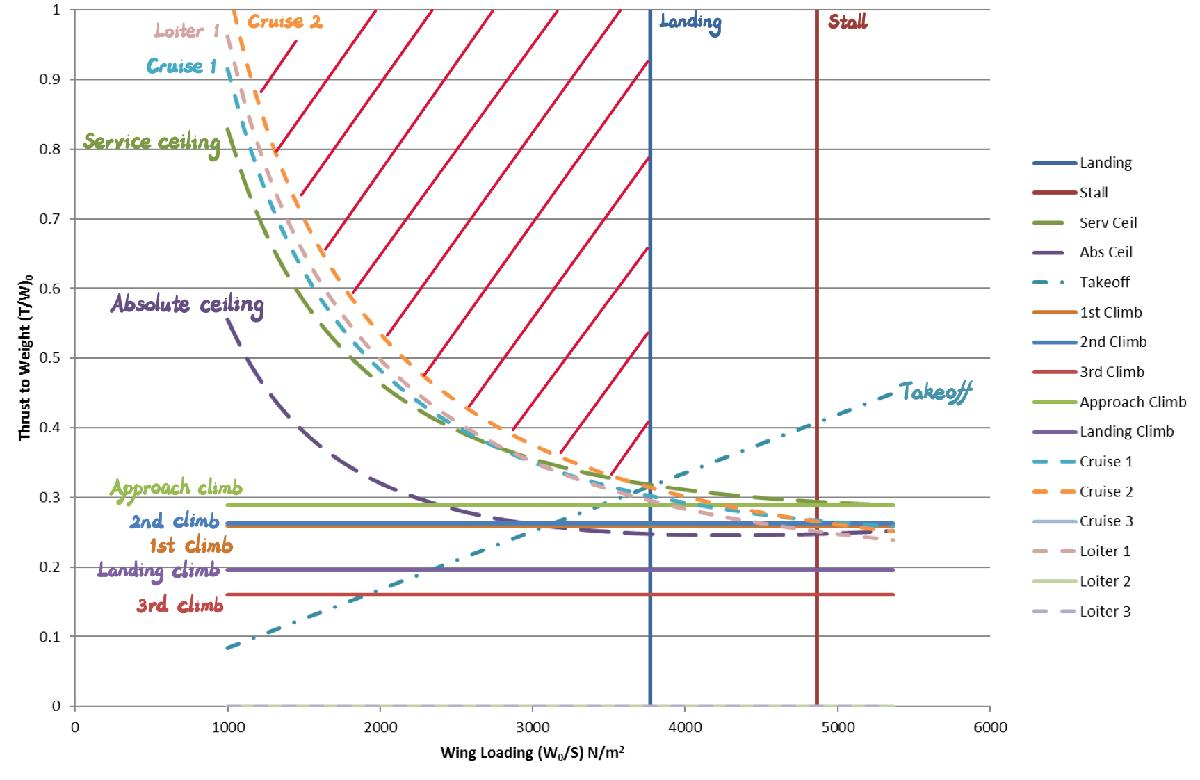

**Constraints**

- **Runway **of minimum length 2900 m

- Resonable **approach speed** shoule be chosen

- **Maximum speed** M = 0.85 at cruise altitude

- **Absolute ceiling** of 45000 ft amsl at Vx

- **Balanced field length **at take off and landing

- Climb gradient

- Descent gradient

## B1 - Point Performance

From defination of **Specific Excess Power (SEP)**

$\frac{\textrm{dh}}{\textrm{dt}}$ (Climb) $+\frac{{\mathit{\mathbf{V}}}_{\infty } }{\mathit{\mathbf{g}}}\frac{{\textrm{dV}}_{\infty } }{\textrm{dt}}$ (Acceleration) $={\mathit{\mathbf{V}}}_{\infty } \left(\frac{\mathit{\mathbf{T}}-\mathit{\mathbf{D}}}{\mathit{\mathbf{W}}}\right)$ 

for** Drag**, assuming a parabolic drag curve at load factor n

$\frac{D}{W}=\frac{\frac{1}{2}\rho {V_{\infty } }^2 C_{D_0 } }{\frac{W}{S_{\textrm{ref}} }}+\frac{n^2 \frac{W}{S_{\textrm{ref}} }}{\frac{1}{2}\rho {V_{\infty } }^2 \pi \textrm{ARe}}$ ( $=\frac{1}{\frac{L}{D}}$ since in most cases $L=W$) 

and dependent on configuration:

Therefore,

 
$$\frac{\textrm{dh}}{\textrm{dt}}+\frac{{\mathit{\mathbf{V}}}_{\infty } }{\mathit{\mathbf{g}}}\frac{{\textrm{dV}}_{\infty } }{\textrm{dt}}\;={\mathit{\mathbf{V}}}_{\infty } \left(\frac{\mathit{\mathbf{T}}}{\mathit{\mathbf{W}}}-\frac{\frac{1}{2}\rho {{\mathit{\mathbf{V}}}_{\infty } }^2 {\mathit{\mathbf{C}}}_{{\mathit{\mathbf{D}}}_0 } }{\frac{\mathit{\mathbf{W}}}{{\mathit{\mathbf{S}}}_{\textrm{ref}} }}-\frac{{\mathit{\mathbf{n}}}^2 \frac{\mathit{\mathbf{W}}}{{\mathit{\mathbf{S}}}_{\textrm{ref}} }}{\frac{1}{2}\rho {{\mathit{\mathbf{V}}}_{\infty } }^2 \pi \textrm{ARe}}\;\right)$$
 

or


$$\frac{\mathit{\mathbf{T}}}{\mathit{\mathbf{W}}}=\frac{1}{V_{\infty } }\frac{\textrm{dh}}{\textrm{dt}}+\frac{1}{\mathit{\mathbf{g}}}\frac{{\textrm{dV}}_{\infty } }{\textrm{dt}}+\frac{\frac{1}{2}\rho {{\mathit{\mathbf{V}}}_{\infty } }^2 {\mathit{\mathbf{C}}}_{{\mathit{\mathbf{D}}}_0 } }{\frac{\mathit{\mathbf{W}}}{{\mathit{\mathbf{S}}}_{\textrm{ref}} }}+\frac{{\mathit{\mathbf{n}}}^2 \frac{\mathit{\mathbf{W}}}{{\mathit{\mathbf{S}}}_{\textrm{ref}} }}{\frac{1}{2}\rho {{\mathit{\mathbf{V}}}_{\infty } }^2 \pi \textrm{ARe}}$$
 

Scaling to sea-level, static, takeoff conditions

$\alpha =\frac{\mathit{\mathbf{W}}}{{\mathit{\mathbf{W}}}_0 }$ (see initial sizing) and $\beta =\frac{\mathit{\mathbf{T}}}{{\mathit{\mathbf{T}}}_0 }$ (function of Mach number and altitude)

Hence for jet, at sea level


$${\left(\frac{\mathit{\mathbf{T}}}{\mathit{\mathbf{W}}}\right)}_0 =\frac{\alpha }{\beta }\left(\frac{1}{V_{\infty } }\frac{\textrm{dh}}{\textrm{dt}}+\frac{1}{\mathit{\mathbf{g}}}\frac{{\textrm{dV}}_{\infty } }{\textrm{dt}}+\frac{\frac{1}{2}\rho {{\mathit{\mathbf{V}}}_{\infty } }^2 {\mathit{\mathbf{C}}}_{{\mathit{\mathbf{D}}}_0 } }{\frac{\mathit{\mathbf{W}}}{{\mathit{\mathbf{S}}}_{\textrm{ref}} }}+\frac{{\mathit{\mathbf{n}}}^2 \frac{\mathit{\mathbf{W}}}{{\mathit{\mathbf{S}}}_{\textrm{ref}} }}{\frac{1}{2}\rho {{\mathit{\mathbf{V}}}_{\infty } }^2 \pi \textrm{ARe}}\right)$$
 

T0_W0 = @(alpha, beta, dh_dt, dV_dt, W0_Sref, AR, e, V, CD0, n, rho) ...
    alpha ./ beta .* (1 ./ V .* dh_dt + 1 ./ g .* dV_dt + ...
    (0.5 .* rho .* V .^ 2 .* CD0) ./ (alpha .* W0_Sref) + ...
    (alpha .* n .^ 2 .* W0_Sref) ./ (0.5 .* rho .* V .^ 2 .* pi .* AR .* e));

${\left(\frac{T}{W}\right)}_0$ can be plotted against $\frac{W_0 }{S}$ at each stage (especially cruising), at different: 

- Mach number, $M$

- Aspect ratio,$\textrm{AR}$

- state of flight, $\frac{W}{W_0 }$ and $\frac{T}{T_0 }$

- Load factor, $n$

- Climb rate, $\frac{\textrm{dh}}{\textrm{dt}}$

## B2 - Field Performance

### B2.1 - Takeoff

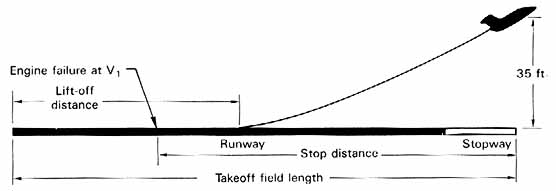

The velocity (**decision speed**) at balanced field length is taken as ${\mathit{\mathbf{V}}}_1$

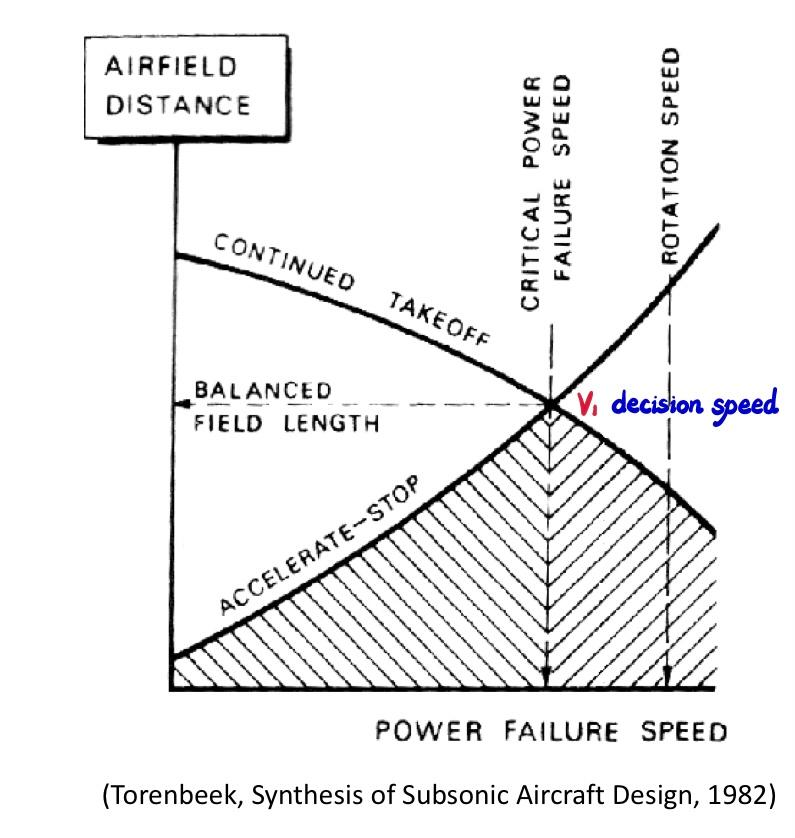

Parameters affecting **Takeoff Distance**:

- Stall Speed, $V_S =f\left(\rho ,\frac{W}{S},{\left(C_{l_{\max } } \right)}_{\textrm{takeoff}} \right)$

- Ground Acceleration, $f\left(\frac{T}{W},W,C_{D_0 } ,\mu \right)$

- Excess Power,  $\textrm{ESP}=f\left(\frac{T}{W},\frac{W}{S},C_{D_0 } ,N_E \right)\;$

- Obstacle Height

**Empirically**, in SI unit,** Take Off Distance Available (TODA) **: 

- $\textrm{TODA}\ge \left(0\ldotp 297-0\ldotp 019{\mathit{\mathbf{N}}}_{\mathit{\mathbf{E}}} \right)\textrm{TOP}\;$ for Balance Field Length (BFL)

- $\textrm{TODA}\ge 0\ldotp 144\textrm{TOP}\;$ for All Engine Operative (AEO) to 50 ft

where $\textrm{TOP}=\frac{\frac{\mathit{\mathbf{W}}}{\mathit{\mathbf{S}}}}{\frac{\mathit{\mathbf{T}}}{\mathit{\mathbf{W}}}{\sigma \left(C_L \right)}_{\textrm{TOF}} }$

### B2.2 - Landing

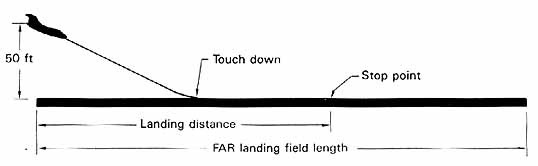

Parameters affecting** Landing Distance**

- Approach Speed, $f\left(\rho ,\frac{W}{S},{\left(C_{l_{\max } } \right)}_{\textrm{landing}} \right)$

- Deceleration,  $f\left(\frac{T}{W},W,T_{\textrm{reverse}} \right)$

- Glide Slope, $f\left(\gamma_{\textrm{approach}} \right)$

- Obstacle Height

**Empirically**, in SI unit,** Available Landing Distance (ALD) **: 


$$\textrm{ALD}=0\ldotp 51\frac{\frac{W}{S}}{{\sigma \left(C_{L_{\max } } \right)}_{\textrm{landing}} }K_R +S_a$$


where $S_a$ is the **approach distance** (from start to touch down)

$K_R$ is the correction factor for deceleration, accounts for (eg. thrust reverse has $K_R$=0.66)

### B2.3 - High Lift Device

Affects $C_{L_{\max } }$

[*https://www.aircraftinvestigation.info/airplanes/A330-900.html*](https://www.aircraftinvestigation.info/airplanes/A330-900.html)


$${\left(C_{l_{\max } } \right)}_{\textrm{takeoff}} \approx 0\ldotp 8{\left(C_{L_{\max } } \right)}_{\textrm{landing}}$$
  

**Basic Parameters**

CD_0 = 0.0212; % Drag ceofficient at zero lift % Boeing 777-300ER
e = 0.69;      % Oswald/span efficiency factor % Boeing 777-300ER

% Need to be change
CL_max_L = 2.5;              % Maximum lift coefficient in landing configuration
CL_max_TO = CL_max_L .* 0.8; % Maximum lift coefficient in take-off configuration
CL_max_C = 1.25;             % Maximum lift coefficient in cruise configuration
% V_S = convvel(137, 'kts', 'm/s') % Stall speed at sea level% Boeing 777-300ER

% Guessed Wing Loading
W0_Sref = linspace(100,15000,500);

**Maximum achievable **${\left(\frac{T}{W}\right)}_0$ (Curve descend with wing loading)

T0_W0_Max = NE * T_0 / (W_0 * g);

**Landing with Reverse Device ON **(Vertical straight line)

Basic Parameters

% sigma = 1;   % Landing site ASL
% Sa = 305;    % Airliner type 3 degree glideslope
% KR_1 = 0.66; % Correction factor for thrust reverse device
% ALD = 2900;  % Runway length (m)

Calculate weight ratio (by Raymer)

alpha_landing = W_i(1) * W_i(2) * W_i(3) * W_i(4); % * W_i(5) * W_i(6) * W_i(7) * W_i(8);
% alpha_landing = 0.73; % Maximum landing weight % www.aircraftinvestigation.info

Calculate ${\left(\frac{T}{W}\right)}_0$

% W_S_Landing_1 = (ALD * 0.6 - Sa) * (sigma * CL_max_L) / 5.3; % Where did this equation comes from? Where is KR? Where is Sa?
% W0_S_Landing_1 = W_S_Landing_1  / alpha_landing * g;

**Landing with Reverse Device OFF **(Vertical straight line)

Basic Parameters

sigma = 1;   % Landing site ASL
Sa = 305;    % Airliner type 3 degree glideslope
% KR_2 = 1;   % Correction factor for thrust reverse device
ALD = 2900;  % Runway length (m)

Calculate ${\left(\frac{T}{W}\right)}_0$

W_S_Landing = g * (ALD * 0.6 - Sa) * (sigma * CL_max_L) / (0.51 * g); % Regression data % www.aircraftinvestigation.info
W0_S_Landing = W_S_Landing / alpha_landing;

% Housekeeping
clearvars W_S_Landing

**Find stall speed **(Vertical straight line)

$S_{\textrm{FL}} =\frac{S_L }{0\ldotp 6}$ and $S_{\textrm{FL}} =0\ldotp 3V_A^2$ and $V_A =1\ldotp 3V_S$ from Roskam Part I (p.110)

S_L = convlength(ALD, 'm', 'ft');
S_FL = S_L ./ 0.6;
V_A = (S_FL ./ 0.3) .^ 0.5;
V_S = V_A ./ 1.3';
V_S = convvel(V_S, 'kts', 'm/s')

V_S = 90.9809

V_A = convvel(V_A, 'kts', 'm/s')

V_A = 118.2752

$V_S =\sqrt{\frac{2W}{\rho_{0\;} S_{\textrm{ref}} {\;C}_{L_{\max } } }}$ in landing configurations, therefore


$$\frac{W_0 }{S_{\textrm{ref}} }=\;\frac{1}{2}\rho_0 \;V_S^2 \;{\left(C_{L_{\max } } \right)}_{\textrm{landing}}$$


[T_0, c_0, P_0, rho_0] = atmosisa(0);

W0_Sref_Stall = 0.5 * rho_0 * V_S ^ 2 * CL_max_L;

% Housekeeping
clearvars S_FL S_L

**1st Cruise **(Curve descend with wing loading)

h_cruise1 = convlength(39000, 'ft','m'); % Cruise altitude (m) % Boeing 777 % Wikipedia

[T_cruise1, c_cruise1, P_cruise1, rho_cruise1] = atmosisa(h_cruise1);

V_cruise1 = 0.83 * c_cruise1;            % Cruise velocity (m/s)

Calculate $\frac{W}{W_0 }$ (by Raymer)

alpha_cruise1_0 = W_i(1) * W_i(2);          % At the start of cruise 1
alpha_cruise1_f = W_i(1) * W_i(2) * W_i(3); % At the end of cruise 1

Calculate $\frac{T}{T_0 }$

% Need to be change
beta_cruise1 = T_T0(h_cruise1); % Ignore effect of M % Intro to Aerospace p.83

Calculate ${\left(\frac{T}{W}\right)}_0$

% T0_W0 = @(alpha, beta, dh_dt, dV_dt, W0_Sref, AR, e, V, CD0, n, rho)
T0_W0_cruise1_0 = T0_W0(alpha_cruise1_0, beta_cruise1, 0.0, 0.0, W0_Sref, AR, e, V_cruise1, CD_0, 1, rho_cruise1);
T0_W0_cruise1_f = T0_W0(alpha_cruise1_f, beta_cruise1, 0.0, 0.0, W0_Sref, AR, e, V_cruise1, CD_0, 1, rho_cruise1);

Calculate Indicated Minimum Drag Speed $V_{\textrm{imD}}$, which will be used in loiter section

according to $V_{\textrm{maxSAR}} =\frac{V_{i\;\textrm{maxSAR}} }{\sqrt{\sigma }}=\sqrt[4]{3}\frac{V_{\textrm{imD}} }{\sqrt{\sigma }}$ (Intro to Aerospace p.110)

V_imD = V_cruise1 .* (rho_cruise1 ./ rho_0) .^ 0.5 ./ ((3) .^ 0.25);

% Housekeeping
clearvars h_cruise1 T_cruise1 c_cruise1 P_cruise1 rho_cruise1 V_cruise1
clearvars alpha_cruise1_0 alpha_cruise1_f beta_cruise1

**2nd Cruise **(Curve descend with wing loading)

h_cruise2 = convlength(18000, 'ft','m'); % Alternate altitude for Lost Communications Missed Approach (m) % Ref 5

[T_cruise2, c_cruise2, P_cruise2, rho_cruise2] = atmosisa(h_cruise2);

V_cruise2 = convvel(400, 'kts', 'm/s');  % Alternate velocity (m/s)

Calculate $\frac{W}{W_0 }$ (by Raymer)

alpha_cruise2_0 = W_i(1) * W_i(2) * W_i(3) * W_i(4) * W_i(5);          % At the start of cruise 2
alpha_cruise2_f = W_i(1) * W_i(2) * W_i(3) * W_i(4) * W_i(5) * W_i(6); % At the end of cruise 2

Calculate $\frac{T}{T_0 }$

% Need to be change

beta_cruise2 = T_T0(h_cruise2); % Ignore effect of M % Intro to Aerospace p.83

Calculate ${\left(\frac{T}{W}\right)}_0$

% T0_W0 = @(alpha, beta, dh_dt, dV_dt, W0_Sref, AR, e, V, CD0, n, rho)
T0_W0_cruise2_0 = T0_W0(alpha_cruise2_0, beta_cruise2, 0.0, 0.0, W0_Sref, AR, e, V_cruise2, CD_0, 1, rho_cruise2);
T0_W0_cruise2_f = T0_W0(alpha_cruise2_f, beta_cruise2, 0.0, 0.0, W0_Sref, AR, e, V_cruise2, CD_0, 1, rho_cruise2);

% Housekeeping
clearvars h_cruise2 T_cruise2 c_cruise2 P_cruise2 rho_cruise2 V_cruise2
clearvars alpha_cruise2_0 alpha_cruise2_f beta_cruise2

**Cruise at maximum speed (M = 0.85) **(Curve descend with wing loading)

h_cruiseMAX = convlength(39000, 'ft','m'); % Cruise altitude (m) % Boeing 777 % Wikipedia

[T_cruiseMAX, c_cruiseMAX, P_cruiseMAX, rho_cruiseMAX] = atmosisa(h_cruiseMAX);

V_cruiseMAX = 0.85 * c_cruiseMAX;            % Maximum velocity (m/s)

Calculate $\frac{W}{W_0 }$ (by Raymer)

alpha_cruiseMAX_0 = W_i(1) * W_i(2);          % At the start of cruise max
alpha_cruiseMAX_f = W_i(1) * W_i(2) * W_i(3); % At the end of cruise max

Calculate $\frac{T}{T_0 }$

% Need to be change
beta_cruiseMAX = T_T0(h_cruiseMAX); % Ignore effect of M % Intro to Aerospace p.83

Calculate ${\left(\frac{T}{W}\right)}_0$

% T0_W0 = @(alpha, beta, dh_dt, dV_dt, W0_Sref, AR, e, V, CD0, n, rho)
T0_W0_cruiseMAX_0 = T0_W0(alpha_cruiseMAX_0, beta_cruiseMAX, 0.0, 0.0, W0_Sref, AR, e, V_cruiseMAX, CD_0, 1, rho_cruiseMAX);
T0_W0_cruiseMAX_f = T0_W0(alpha_cruiseMAX_f, beta_cruiseMAX, 0.0, 0.0, W0_Sref, AR, e, V_cruiseMAX, CD_0, 1, rho_cruiseMAX);

% Housekeeping
clearvars h_cruiseMAX T_cruiseMAX c_cruiseMAX P_cruiseMAX rho_cruiseMAX V_cruiseMAX
clearvars alpha_cruiseMAX_0 alpha_cruiseMAX_f beta_cruiseMAX

**Absolute Ceiling **(Horizontal straight line)ccvcc

absCeiling = convlength(45000,'ft','m'); % Absolute Ceiling

Calculate $\frac{W}{W_0 }$ (by Raymer)

alpha_absCeiling = W_i(1) * W_i(2);      % At the start of cruise 1

Calculate $\frac{T}{T_0 }$

% Need to be change
beta_absCeiling = T_T0(absCeiling);      % Ignore effect of M % Intro to Aerospace p.83

Calculate ${\left(\frac{T}{W}\right)}_0$ according to $T=\frac{2W}{\sqrt{\frac{\pi \textrm{ARe}}{C_{D_0 } }}}$ (Intro to Aerospace p.119) 

Therefore,


$${\left(\frac{T}{W}\right)}_0 =\frac{2\alpha }{\beta \sqrt{\frac{\pi \textrm{ARe}}{C_{D_0 } }}}$$


T0_W0_abs = (2 * alpha_absCeiling) / (beta_absCeiling * ((pi * AR * e) / CD_0) ^ 0.5);

% Housekeeping
clearvars absCeiling alpha_absCeiling beta_absCeiling

**Service Ceiling **(Not sure if can be calculated here)

dh_dt_service = convvel(500,'ft/min','m/s'); % FAR requires 500 ft/min for jet % Raymer p.670
dV_dt_service = 0;                           % Assuming steady climb

% Housekeeping
clearvars dh_dt_service dV_dt_service

**Loiter**

Basic parameters

n = 1; % Load factor

h_loiter = convlength(5000, 'ft','m'); % Alternate altitude (m)

[T_loiter, c_loiter, P_loiter, rho_loiter] = atmosisa(h_loiter);

Calculate $\frac{W}{W_0 }$ (by Raymer)

alpha_loiter = W_i(1) * W_i(2) * W_i(3) * W_i(4) * W_i(5) * W_i(6); % At the start of loiter

Calculate loitering speed, $V=V_{\textrm{mD}} =\frac{V_{\textrm{imD}} }{\sqrt{\sigma }}$

V_mD = V_imD ./ ((rho_loiter ./ rho_0) .^ 0.5);

Calculate $\frac{T}{T_0 }$

% Need to be change
beta_loiter = T_T0(h_loiter); % Ignore effect of M % Intro to Aerospace p.83

Calculate ${\left(\frac{T}{W}\right)}_0$

% T0_W0 = @(alpha, beta, dh_dt, dV_dt, W0_Sref, AR, e, V, CD0, n, rho)
T0_W0_loiter = T0_W0(alpha_loiter, beta_loiter, 0.0, 0.0, W0_Sref, AR, e, V_mD, CD_0, 1, rho_loiter);

% Housekeeping
clearvars n h_loiter T_loiter c_loiter P_loiter rho_loiter
clearvars alpha_loiter V_imD beta_loiter

**Takeoff **(Straight line)

Basic Parameters

sigma = 1;   % Takeoff site ASL
TODA = 2900; % Runway length (m)

Calculate ${\left(\frac{T}{W}\right)}_0$

$\textrm{AEO}$ to 50 ft (FAR 23 not FAR 25)

T0_W0_AEO = 1.15 .* 0.144 .* W0_Sref ./ (sigma * CL_max_TO * TODA);


$$\textrm{BFL}\;4N_E$$
 

T0_W0_BFL = (0.297 - 0.019 * NE) .* W0_Sref ./ (sigma * CL_max_TO * TODA);
% T0_W0_BFL = 4.45 * 10 ^ (-5) .* W0_Sref .* 2.034 .* 0.85 ./ CL_max_TO; % Regression data % www.aircraftinvestigation.info

**1st Climb and accelerate  **(Horizontal straight line)

steady gradient of climb must not be less than 1.2 percent of twin engine airplanes

At take-off velocity $V_2$, it should be not less than $1\ldotp 13V_{\textrm{Stall}}$ for twin engine. Ensure it could reach this speed by the time it reaches a height of 35 feet above takeoff surface.

*Climbing at 7 degrees (assumption) of slope at *$V_2 =1\ldotp 2V_{\textrm{Stall}}$ *find source to back the climb angle, regression analysis\*

Basic Parameters

V_TO = 1.2 * V_S;                        % Take off velocity (m/s)
theta1 = 7 * pi / 180;                  % Climb angle (rad) % twin engine % FAR
h_climb1 = convlength(39000,'ft','m');  % Cruise altitude (m) % Boeing 777 % Wikipedia

[T_cruise1, c_cruise1, P_cruise1, rho_cruise1] = atmosisa(h_climb1);

V_cruise1 = 0.83 * c_cruise1;           % Cruise velocity (m/s)

dh_dt_climb1 = V_TO * sin(theta1);        % Climb rate (m/s)
%use a prescribed climb rate, 1350 m/ min
%dh_dt_climb1 = 800/60;

Airplane should reach cruise speed at cruise altitude

T_climb1 = h_climb1 / (dh_dt_climb1);  % The climb time assumed constant climb rate (s)
dV_dt_climb1 = (V_cruise1 - V_TO) / T_climb1;  % The average acceleration (m/s^2)

Calculate $\frac{W}{W_0 }$ (by Raymer)

alpha_climb1_0 = W_i(1);          % At the start of 1st climb
alpha_climb1_f = W_i(1) * W_i(2); % At the end of 1st climb

Calculate $\frac{T}{T_0 }$

% Need to be change
beta_climb1_0 = T_T0(0);        % At the start of 1st climb % Ignore effect of M % Intro to Aerospace p.83
beta_climb1_f = T_T0(h_climb1); % At the end of 1st climb % Ignore effect of M % Intro to Aerospace p.83

Calculate ${\left(\frac{T}{W}\right)}_0$

T0_W0_climb1_0 = T0_W0(alpha_climb1_0, beta_climb1_0, dh_dt_climb1, dV_dt_climb1, W0_Sref, AR, e, V_TO, CD_0, 1, 1);
T0_W0_climb1_f = T0_W0(alpha_climb1_f, beta_climb1_f, dh_dt_climb1, dV_dt_climb1, W0_Sref, AR, e, V_TO, CD_0, 1, 1);

% Housekeeping
clearvars  c_cruise1 P_cruise1 rho_cruise1
clearvars theta1 h_climb1  dV_dt_climb1
clearvars alpha_climb1_0 alpha_climb1_f beta_climb1_0 beta_climb1_f

**2nd Climb after mised approach**

Refer to **'landing climb'** in FAR25

must not be less than 3.2 degrees, so this is a minimum requirement for $\frac{T}{W}$ ratio

Go-around at landing velocity

*Climb at the same angle as takeoff climb, at *$V_2$

theta2 = 3.6 * pi / 180;           % Climb angle (rad) % landing climb % FAR

dh_dt_climb2 = V_TO * sin(theta2);  % Climb rate (m/s)
%dh_dt_climb2 = dh_dt_climb1; %same climb rate
h_climb2 = convlength(18000, 'ft','m'); % Alternate altitude for Lost Communications Missed Approach (m) % Ref 5
V_cruise2 = convvel(400, 'kts', 'm/s'); % Alternate velocity (m/s)                                      % Ref 5

Airplane should reach cruise speed at cruise altitude

T_climb2 = h_climb2 / (dh_dt_climb2);        % The climb time assumed constant climb rate (s)
dV_dt_climb2 = (V_cruise2 - V_TO) / T_climb2; % The average acceleration (m/s^2)

Calculate $\frac{W}{W_0 }$ (by Raymer)

alpha_climb2_0 = W_i(1) * W_i(2) * W_i(3) * W_i(4);          % At the start of 2nd climb
alpha_climb2_f = W_i(1) * W_i(2) * W_i(3) * W_i(4) * W_i(5); % At the end of 2nd climb

Calculate $\frac{T}{T_0 }$

% Need to be change
beta_climb2_0 = T_T0(0);        % At the start of 2nd climb % Ignore effect of M % Intro to Aerospace p.83
beta_climb2_f = T_T0(h_climb2); % At the end of 2nd climb   % Ignore effect of M % Intro to Aerospace p.83

Calculate ${\left(\frac{T}{W}\right)}_0$

T0_W0_climb2_0 = T0_W0(alpha_climb2_0, beta_climb2_0, dh_dt_climb2, dV_dt_climb2, W0_Sref, AR, e, V_TO, CD_0, 1, 1);
T0_W0_climb2_f = T0_W0(alpha_climb2_f, beta_climb2_f, dh_dt_climb2, dV_dt_climb2, W0_Sref, AR, e, V_TO, CD_0, 1, 1);

**ICAO Aerodome Reference Code 4E**

Maximum wing span 65 m

W0_S_ICAO = (W_0 .* g) ./ (65 ^ 2 ./ AR)

W0_S_ICAO = 8.1441e+03

% Housekeeping
clearvars  c_cruise2 P_cruise2 rho_cruise2 i
clearvars theta2 h_climb2 dh_dt_climb2 dV_dt_climb2
clearvars alpha_climb2_0 alpha_climb2_f beta_climb2_0 beta_climb2_f
clearvars T_0 c_0 P_0 rho_0

**Constraint Diagram**

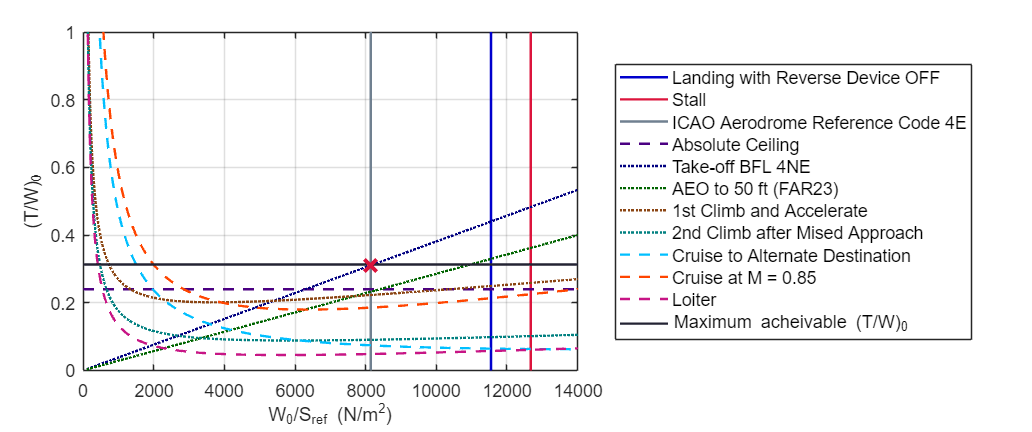

% Find the crossing point

T0_W0_Selected = (0.297 - 0.019 * NE) .* W0_S_ICAO ./ (sigma * CL_max_TO * TODA);

% Plot the constraint diagram

figure(4)

clf;

plot([W0_S_Landing W0_S_Landing], [0 1], '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5)
hold on % Landing
plot([W0_Sref_Stall W0_Sref_Stall], [0 1], '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5);
hold on % Stall
plot([W0_S_ICAO W0_S_ICAO], [0 1], '-', 'Color', [112/255 128/255 144/255], 'LineWidth', 1.5);
hold on % ICAO Aerodrome Reference Code 4E
plot([0 20000], [T0_W0_abs T0_W0_abs], '--', 'Color', [75/255 0/255 130/255], 'LineWidth', 1.5);
hold on % Absolute Ceiling
plot(W0_Sref, T0_W0_BFL, ':', 'Color', [0/255 0/255 128/255], 'LineWidth', 1.5);
hold on % Take-off BFL 4NE
plot(W0_Sref, T0_W0_AEO, ':', 'Color', [0/255 100/255 0/255], 'LineWidth', 1.5);
hold on % AEO to 50 ft
plot(W0_Sref, T0_W0_climb1_0, ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.5);
hold on % 1st Climb
plot(W0_Sref, T0_W0_climb2_0, ':', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.5);
hold on % 2nd Climb
% plot(W0_Sref, T0_W0_cruise1_0, '--', 'LineWidth', 1.5);
% hold on % 1st Cruise
plot(W0_Sref, T0_W0_cruise2_0, '--', 'Color', [0/255 191/255 255/255], 'LineWidth', 1.5);
hold on % 2nd Cruise
plot(W0_Sref, T0_W0_cruiseMAX_0, '--', 'Color', [255/255 69/255 0/255], 'LineWidth', 1.5);
hold on % Cruise at M=0.85
plot(W0_Sref, T0_W0_loiter, '--', 'Color', [199/255 21/255 133/255], 'LineWidth', 1.5);
hold on % Loiter
plot([0 20000], [T0_W0_Max T0_W0_Max], '-', 'Color', [35/255 35/255 51/255], 'LineWidth', 1.5);
hold on % Maximum acheivable T/W
plot(W0_S_ICAO, T0_W0_Selected, 'x', 'Color', [220/255 20/255 60/255], 'MarkerSize', 11, 'LineWidth', 2.25)
hold off


legend('Landing with Reverse Device OFF', 'Stall', 'ICAO Aerodrome Reference Code 4E', ...
       'Absolute Ceiling', 'Take-off BFL 4NE',...
       'AEO to 50 ft (FAR23)', '1st Climb and Accelerate', '2nd Climb after Mised Approach',...
       'Cruise to Alternate Destination', 'Cruise at M = 0.85', 'Loiter', ...
       'Maximum acheivable (T/W)_{0}', ...
       'Location', 'eastoutside', 'NumColumns', 1, FontSize = 11)

xlabel('W_{0}/S_{ref} (N/m^{2})'); 
ylabel('(T/W)_{0}');

set(gca, 'FontSize', 11) % set the fontsize of the axis

xlim([0 14000]);
ylim([0 1]);

grid on;                             % set the grid of the graph
set(gcf, 'Position', [0 0 860 360]); % show plot with larger size 

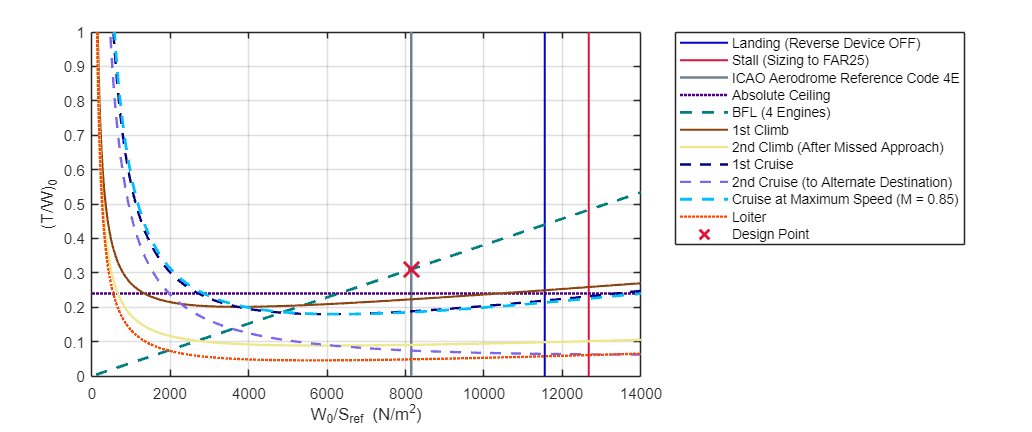

set(gcf, 'Position', [0 0 860 360]); % show plot with larger size 

% Plot the constraint diagram

figure(5)

clf;

plot([W0_S_Landing W0_S_Landing], [0 1], '-', 'Color',  [0/255 0/255 205/255], 'LineWidth', 1.25)
hold on % Landing
plot([W0_Sref_Stall W0_Sref_Stall], [0 1], '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.25);
hold on % Stall
plot([W0_S_ICAO W0_S_ICAO], [0 1], '-', 'Color', [112/255 128/255 144/255], 'LineWidth', 1.5);
hold on % ICAO Aerodrome Reference Code 4E
plot([0 20000], [T0_W0_abs T0_W0_abs], ':', 'Color', [75/255 0/255 130/255], 'LineWidth', 1.5);
hold on % Absolute Ceiling
plot(W0_Sref, T0_W0_BFL, '--', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.75);
hold on % Take-off BFL 4NE
plot(W0_Sref, T0_W0_climb1_0, '-', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.35);
hold on % 1st Climb
plot(W0_Sref, T0_W0_climb2_0, '-', 'Color', [240/255 230/255 140/255], 'LineWidth', 1.5);
hold on % 2nd Climb
plot(W0_Sref, T0_W0_cruise1_0, '--', 'Color', [0/255 0/255 128/255], 'LineWidth', 1.5);
hold on % 1st Cruise
plot(W0_Sref, T0_W0_cruise2_0, '--', 'Color', [123/255 104/255 238/255], 'LineWidth', 1.5);
hold on % 2nd Cruise
plot(W0_Sref, T0_W0_cruiseMAX_0, '--', 'Color', [0/255 191/255 255/255], 'LineWidth', 1.75);
hold on % Cruise at M=0.85
plot(W0_Sref, T0_W0_loiter, ':', 'Color', [255/255 69/255 0/255], 'LineWidth', 1.5);
hold on % Loiter
plot(W0_S_ICAO, T0_W0_Selected, 'x', 'Color', [220/255 20/255 60/255], 'MarkerSize', 13.5, 'LineWidth', 1.75)
hold off


legend('Landing (Reverse Device OFF)', 'Stall (Sizing to FAR25)', 'ICAO Aerodrome Reference Code 4E', ...
       'Absolute Ceiling', 'BFL (4 Engines)',...
       '1st Climb', '2nd Climb (After Missed Approach)', '1st Cruise',...
       '2nd Cruise (to Alternate Destination)', 'Cruise at Maximum Speed (M = 0.85)', 'Loiter', ...
       'Design Point', ...
       'Location', 'northeastoutside', 'NumColumns', 1, FontSize = 8.5)

xlabel('W_{0}/S_{ref} (N/m^{2})'); 
ylabel('(T/W)_{0}');

set(gca, 'FontSize', 9.5) % set the fontsize of the axis

xlim([0 14000]);
ylim([0 1]);

grid on;                             % set the grid of the graph
set(gcf, 'Position', [0 0 860 360]); % show plot with larger size 

**High Lift Device**

Basic Parameters

A = 30 * pi/180;             % Sweep angle (rad)
% W0_Sref_design = W0_S_ICAO; 
Sref = W_0 .* g / W0_S_ICAO; % Reference Area (m^2)
AR_Design = 65 .^ 2 ./ Sref;
cf_c = 1.2;                  % c_flap/c
Sflap_Sref = 0.6;            % S_flap/S_ref

Calculation

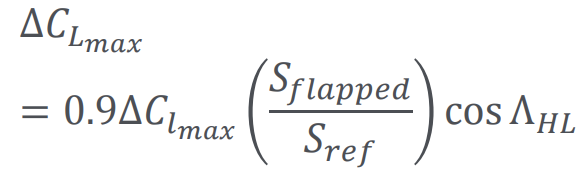

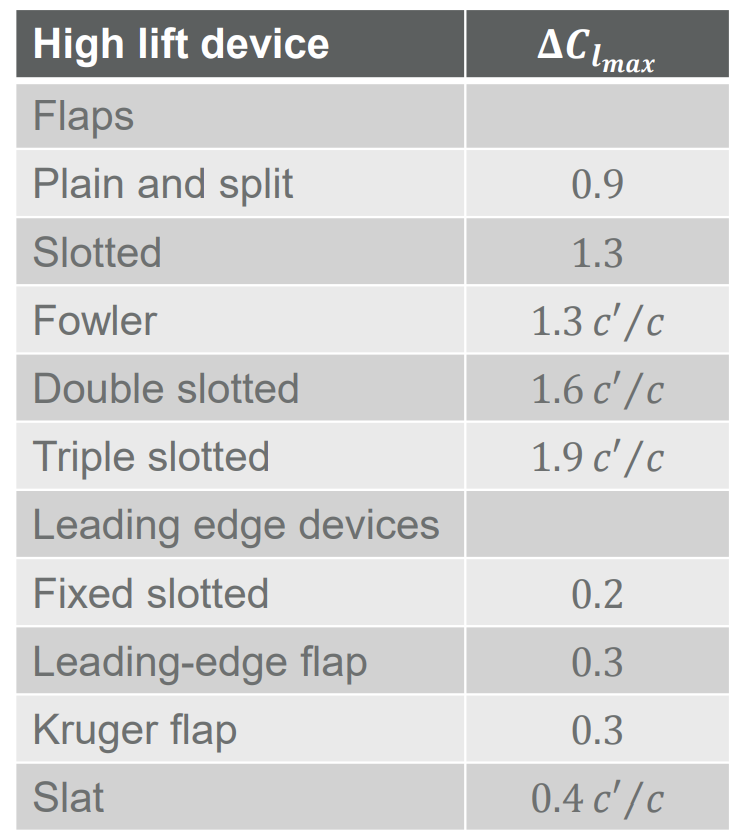

dClmax = [1.3*cf_c, 1.6*cf_c, 1.9*cf_c] % Fowler, Double slotted, Triple slotted

dClmax =     1.5600    1.9200    2.2800


dClmaxLE = [0.2, 0.3, 0.4*cf_c] % Fixed slotted, leading-edge flap, slat

dClmaxLE =     0.2000    0.3000    0.4800


dCLmax = 0.9.*(dClmaxLE(3) + dClmax).*Sflap_Sref*cos(A); % Using slat
%TWRatioBFL = @(W0_Sref,CL_max_TO) 4.45 * 10 ^ (-5) .* W0_Sref*2.034.*0.85./CL_max_TO;
TWRatioBFL = @(W0_Sref,CL_max_TO) (0.297 - 0.019 * NE) .* W0_Sref ./ (sigma * CL_max_TO * TODA);
WL0_Landing = @(ALD,Sa,sigma,CL_max_L,alpha_landing) 9.81 * (ALD * 0.6 - Sa) * (sigma * CL_max_L) / (0.51*9.81)/ alpha_landing; % Regression data % www.aircraftinvestigation.info

CL_max_TO_HLD = 0.8*(CL_max_C + dCLmax);
CL_max_L_HLD = CL_max_C + dCLmax

CL_max_L_HLD =     2.2040    2.3724    2.5407


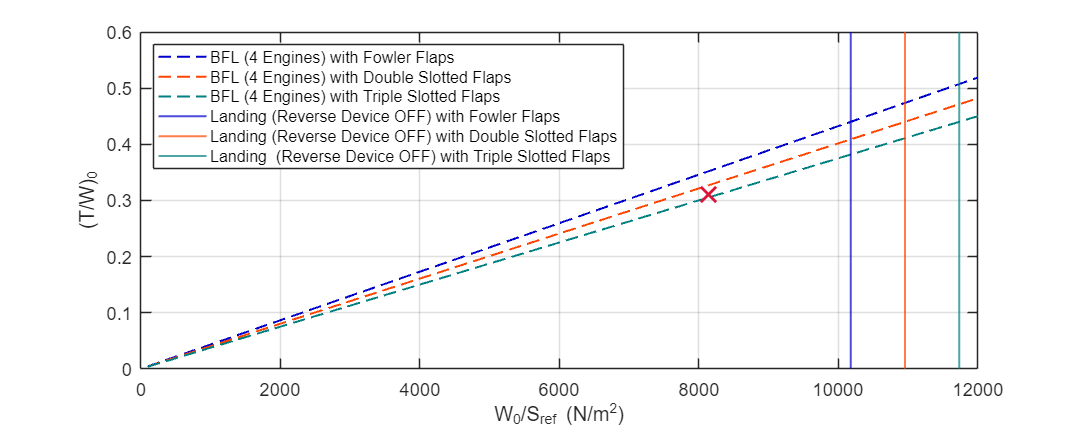


BFLFowler = TWRatioBFL(W0_Sref, CL_max_TO_HLD(1));
BFLDoubleSlotted = TWRatioBFL(W0_Sref, CL_max_TO_HLD(2));
BFLTripleSlotted = TWRatioBFL(W0_Sref, CL_max_TO_HLD(3));

LandingFowler = WL0_Landing(ALD,Sa,sigma,CL_max_L_HLD(1),alpha_landing);
LandingDoubleSlotted = WL0_Landing(ALD,Sa,sigma,CL_max_L_HLD(2),alpha_landing);
LandingTripleSlotted = WL0_Landing(ALD,Sa,sigma,CL_max_L_HLD(3),alpha_landing);

figure(6)
clf;
plot(W0_Sref, BFLFowler, '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.25)
hold on
plot(W0_Sref, BFLDoubleSlotted,  '--', 'Color', [255/255 69/255 0/255], 'LineWidth', 1.25)
hold on
plot(W0_Sref, BFLTripleSlotted, '--', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.25)
hold on
xline(LandingFowler, '-', 'Color',  [0/255 0/255 205/255], 'LineWidth', 1.25)
hold on
xline(LandingDoubleSlotted,  '-', 'Color', [255/255 69/255 0/255], 'LineWidth', 1.25)
hold on
xline(LandingTripleSlotted, '-', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.25)
hold on
plot(W0_S_ICAO, T0_W0_Selected, 'x', 'Color', [220/255 20/255 60/255], 'MarkerSize', 13.5, 'LineWidth', 1.75)
hold off

xlabel('W_{0}/S_ref (N/m^{2})'); 
ylabel('(T/W)_{0}')
legend("BFL (4 Engines) with Fowler Flaps","BFL (4 Engines) with Double Slotted Flaps","BFL (4 Engines) with Triple Slotted Flaps", ...
    "Landing (Reverse Device OFF) with Fowler Flaps","Landing (Reverse Device OFF) with Double Slotted Flaps", ...
    "Landing  (Reverse Device OFF) with Triple Slotted Flaps", "Location", "northwest", 'NumColumns', 1, FontSize = 10)

set(gca, 'FontSize', 11.5) % set the fontsize of the axis

xlim([0 12000]);
ylim([0 0.6]);

grid on;                             % set the grid of the graph
set(gcf, 'Position', [0 0 900 360]); % show plot with larger size 